# Practical Work 1 - CM

Viktoriia Boichenko, EM WAVES, 2022190966

4.11.2022 started by VB

- latex and matlab files create

- parts a),b) : need to solve them on paper

- part c): need to adapt for two different fluids matrix K

- line 96 :%   i was using the point for the analytical solution

## PROBLEM

Consider a 1D problem governed by the Helmholtz equation, in which 𝑝 is the acoustic pressure, 𝑐 the sound propagation velocity and 𝜔 the angular frequency. In this problem, consider the following scenario, in which the propagation medium is composed of two different fluids,  with the following arrangement and boundary conditions: 

The boundary conditions of the system are

- at the left, P=1 Pa

- at the right, $v_x$=0 m/s

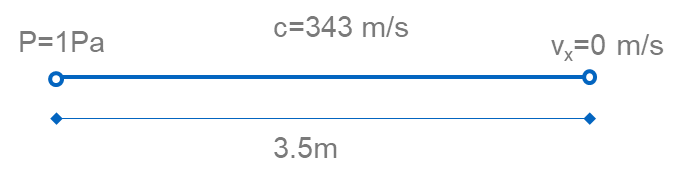

The governing equation is:

$\frac{\partial^2 }{\partial x^2 }P+K^2 P=0$ with $K=\frac{\omega }{c}$

SID 2022190966 -> A1 = 6, A2 = 6

## Solutions

a) For a generic discretization (with spacing ∆𝑥), write the Finite Difference Method (FDM) equations at an internal node of M1, at an internal node of M2, and at the extreme nodes where the boundary conditions are prescribed. 

BC left $P=0$	

BC right $v_x =1$	

The required spatial derivative will be approximated using a second order finite difference scheme 

Node i: $\frac{{\textrm{M1}}_{i-1} -2\cdot \;{\textrm{M1}}_i +{\textrm{M1}}_{i+1} }{\Delta x^2 }+{K_1 }^2 *{\textrm{M1}}_i =0$     $\frac{{\textrm{M2}}_{i-1} -2\cdot \;{\textrm{M2}}_i +{\textrm{M2}}_{i+1} }{\Delta x^2 }+{K_2 }^2 *{\textrm{M2}}_i =0$

b) Consider now a finite element discretization, with 50 linear elements in fluid M1 and 50 in fluid M2. For the node connecting M1 and M2, write the acoustic stiffness and mass matrices of the two elements connected to the node, and establish the corresponding equation of the Finite Element Method (FEM) at that node. 	

$k_e -$the acoustic stiffness matrices

$m_e -$the acoustic mass  matrices


$$k_{\textrm{e50}} =\left\lbrack \begin{array}{cc}
\frac{1}{0,64} & -\frac{1}{0,64}\\
-\frac{1}{0,64} & \frac{1}{0,64}
\end{array}\right\rbrack$$
 
$$m_{\textrm{e50}} =\left\lbrack \begin{array}{cc}
\frac{0,64}{3} & \frac{0,64}{6}\\
\frac{0,64}{6} & \frac{0,64}{3}
\end{array}\right\rbrack$$



$$k_{\textrm{e51}} =\left\lbrack \begin{array}{cc}
\frac{1}{0,74} & -\frac{1}{0,74}\\
-\frac{1}{0,74} & \frac{1}{0,74}
\end{array}\right\rbrack$$
 
$$m_{\textrm{e51}} =\left\lbrack \begin{array}{cc}
\frac{0,74}{3} & \frac{0,74}{6}\\
\frac{0,74}{6} & \frac{0,74}{3}
\end{array}\right\rbrack$$


## FDM

c) Starting from the Matlab codes used in the classes for the FDM, adapting it, and also making use of the analytical solution given in the appendix: 

#### 	1. Calculate the response using 200 points distributed throughout the domain using the finite difference method, and compare the response with the given analytical solution. 

First, discretization of the domain in equally spaced points is performed. 

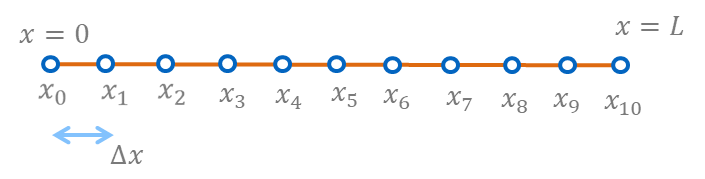

clear;
A1 = 6; 
A2 = 6;
% Dimensions:
L1=20+A1/0.5;
L2=25+A2/0.5;
% The length of the domain
L=L1+L2;
% the number of points for this discretization
npts=200;
% a spacing between points of
dx=L/(npts-1);
%  point coordinates:
x=0:dx:dx*(npts-1);


The parameters of the given PDE (including material properties) must also be defined beforehand.

Fluids M1 and M2 have the same density 

c1=1500.0+10.0*A1-A2; % Fluid M1
c2=(1800.0+20.0*A2+A1)*(1+0.01*1i*(2+sqrt(A1))); % Fluid M2
rho=1.22; % Fluids M1 and M2 have the same density 
freq = 500.0+A2*20.0+A1; % Excitation frequency
w=2*pi*freq;
K1=w/c1;
K2=w/c2;

The boundary conditions of the spatial domain (Dirichlet on the left and Neumann on the right) for the problem can also be stored in variables:

pressure_left=1; %Dirichlet condition
velocity_right=0; %neumann condition

Finally, let us plot this solution:

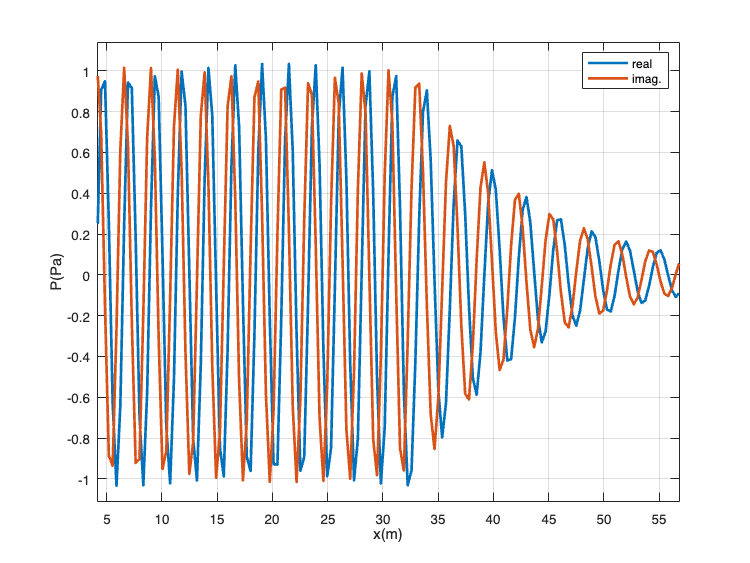

P=fdm_1D(freq,c1,c2,L1,L2,pressure_left, velocity_right, npts, rho);
plot(x,real(P),x,imag(P),'LineWidth',2);grid on;xlabel('x(m)');ylabel('P(Pa)');legend('real','imag.')

xlim([4.2 56.8])
ylim([-1.11 1.14])

Since for this case an analytical solution is known, it is possible to compare the calculated result with the exact solution:

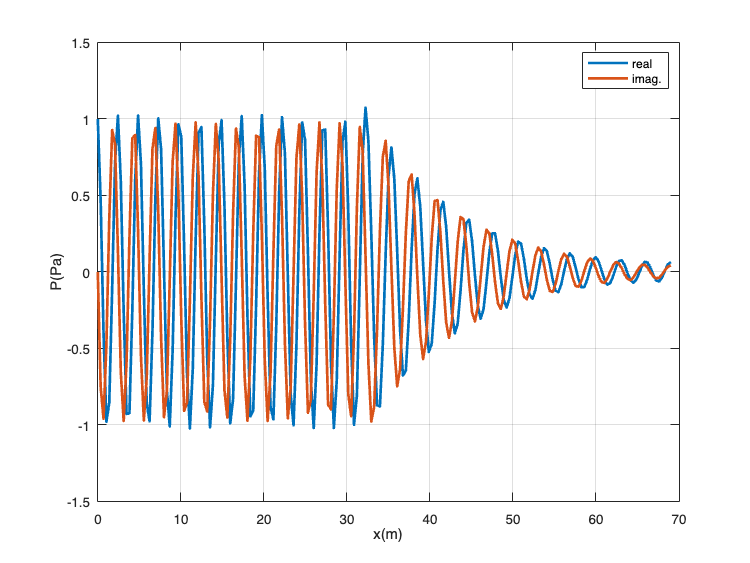

P_s=solution_1D(freq,c1,c2,L1,L2,x);
plot(x,real(P_s),x,imag(P_s),'LineWidth',2);grid on;xlabel('x(m)');ylabel('P(Pa)');legend('real','imag.')

#### Compare the response with the given analytical solution

Real part has the same beginning, but difference between two solutions gradually starts to appear. Imaginary part of the numerical solution has higher range and goes off in the end points 

#### 2. For discretizations starting at 100 points and then progressively increasing this number (use at least 10 different discretizations), calculate the error in the numerical estimation of the pressure (P) at the interface between the two media, and represent the result as a convergence curve (in a Log-Log scale), representing the number of points in the horizontal axis and the absolute error in the vertical axis. 


$$\varepsilon = |P_A - P_{FD}|$$
 

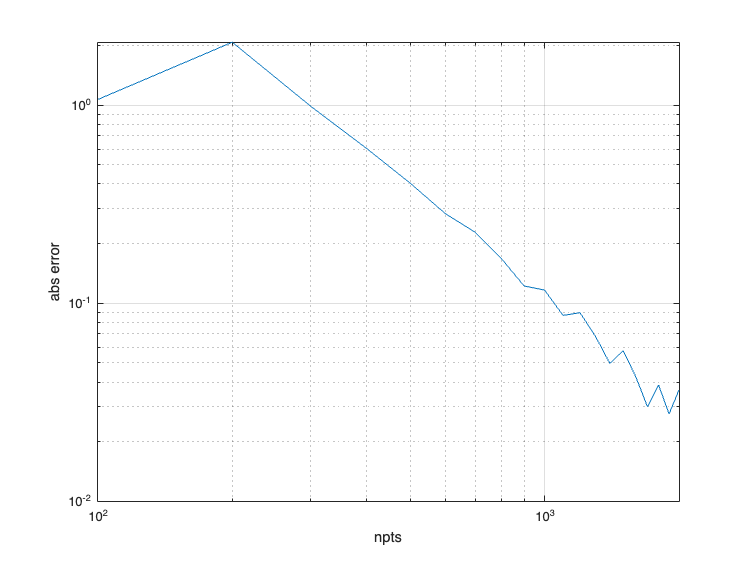

ndiscr = 20;
x_plot = 100:100:100*ndiscr;
y_plot = zeros(1,ndiscr);

for ii=1:ndiscr
%     the number of points for this discretization
    npts=x_plot(ii); 
    dx=(L1+L2)/(npts-1);
    x=0:dx:(L1+L2);

%     Calculation numerical and analytical solution
    P=fdm_1D(freq,c1,c2,L1,L2,pressure_left,velocity_right,npts,rho);
    P_s=solution_1D(freq,c1,c2,L1,L2,x);

%   the numerical estimation of the pressure (P) at the interface between the two media
    x1=0;
    for jj=floor(L1/dx):npts-1
        if(x(jj)>=L1)
            x1=jj-1;
            break
        end
    end

    a=L1-x(x1); b=x(x1+1)-L1;
    p_num =(P(x1)*b+P(x1+1)*a)/dx;
    p_analytical =(P_s(x1)*b+P_s(x1+1)*a)/dx;
    y_plot(ii) = abs(p_analytical-p_num);
end
loglog(x_plot,y_plot);
grid on;xlabel('npts');ylabel('abs error');

## FEM

d)  Starting from the Matlab codes used in the classes for the **FEM**, adapting them, and also making use of the analytical solution given in the appendix: 

    1. Discretize the domain using a maximum element size of 0.5m, and compute the solution using the FEM. Compare the response with the given analytical solution. 								

clear;
A1 = 6; 
A2 = 6;
% Dimensions:
L1=20+A1/0.5;
L2=25+A2/0.5;
% The length of the domain
L=L1+L2;
% a spacing between points 
dx=0.5;
x=0:dx:L;

% velocities in fluids
c1=1500.0+10.0*A1-A2; % Fluid M1
c2=(1800.0+20.0*A2+A1)*(1+0.01*1i*(2+sqrt(A1))); % Fluid M2

rho=1.22; % Fluids M1 and M2 have the same density 
freq = 500.0+A2*20.0+A1; % Excitation frequency
w=2*pi*freq;

FEM solution of pressure over two fluids with a element size of 0.5 m

P = fem_1D(freq,c1,c2,L1,L2,L1/dx,L2/dx,rho)

P =    1.0000 + 0.0000i
   0.5520 - 0.9629i
  -0.5938 - 0.7085i
  -0.9889 + 0.4415i
  -0.1339 + 1.0334i
   0.8904 + 0.3190i
   0.7891 - 0.7987i
  -0.3097 - 0.9067i
  -1.0170 + 0.1315i
  -0.4387 + 1.0035i


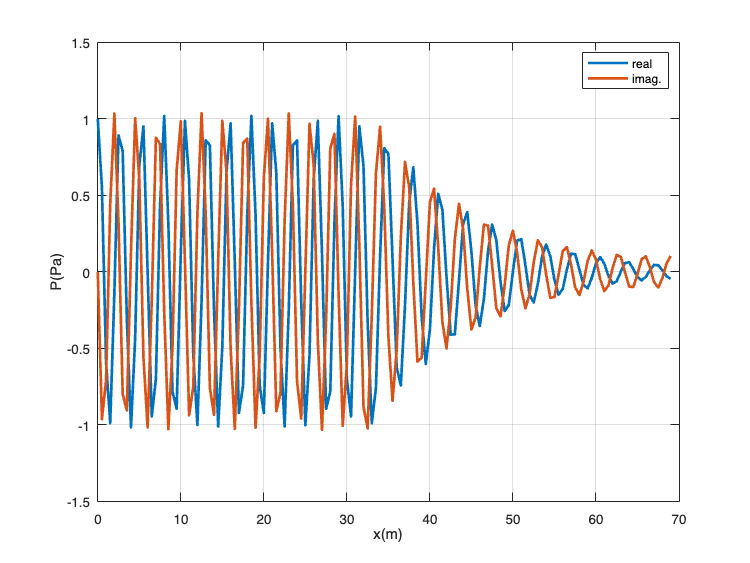

plot(x,real(P),x,imag(P),'LineWidth',2);grid on;xlabel('x(m)');ylabel('P(Pa)');legend('real','imag.')

P_s = solution_1D(freq,c1,c2,L1,L2,x)

P_s =    1.0000 - 0.0000i
   0.0915 - 0.9313i
  -0.9450 - 0.5598i
  -0.6596 + 0.5948i
   0.5485 + 0.9173i
   0.9893 - 0.0434i
   0.0461 - 0.9434i
  -0.9615 - 0.5237i
  -0.6241 + 0.6286i
   0.5864 + 0.9015i


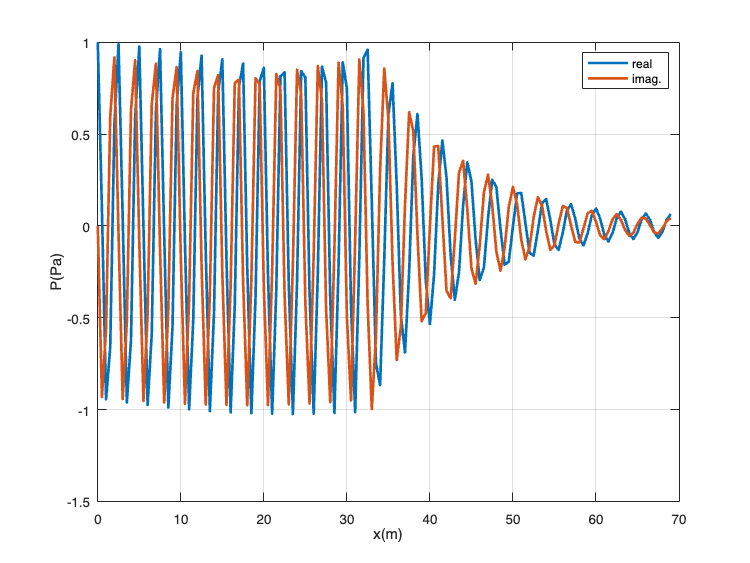

plot(x,real(P_s),x,imag(P_s),'LineWidth',2);grid on;xlabel('x(m)');ylabel('P(Pa)');legend('real','imag.')

For successively finer discretizations, starting with an element size of approximately 1.0 m and then reducing the element size (use at least 10 different discretizations), calculate the error in the numerical estimation of the pressure (P) at interface between the two media, and represent the result as a convergence curve (in a Log-Log scale), representing the total number of nodes in the horizontal axis and the absolute error in the vertical axis. 	

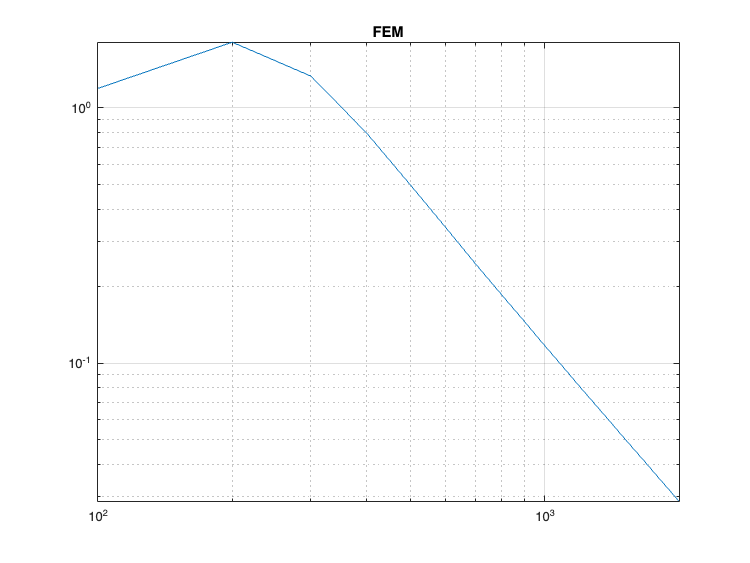

ndiscr = 20;
x_plot = 100:100:100*ndiscr;
% x_plot = L:L:L*ndiscr;
y_fem_plot = zeros(1,ndiscr);

% different discretization for each length
for ii=1:ndiscr
%     element size
    npts=x_plot(ii);
    n1=round(npts*L1/L,0);   n2=round(npts*L2/L,0);
    dx1=L1/n1;      dx2=L2/n2;
    x_range1=0:dx1:L1;
    x_range2=L1:dx2:L;
    x = [x_range1 x_range2];
    x(npts+1)=[];
%     Calculation numerical and analytical solution
    P=fem_1D(freq,c1,c2,L1,L2,n1,n2,rho);
    P_s=solution_1D(freq,c1,c2,L1,L2,x);
%   the numerical estimation of the pressure (P) at the interface between the two media
    y_fem_plot(ii) = abs(P_s(n1)-P(n1));
   
end
loglog(x_plot, y_fem_plot)
title('FEM')
grid on

Adding FDM plot for comparison

y_fdm_plot = zeros(1,ndiscr);

for ii=1:ndiscr
%     the number of points for this discretization
    npts=x_plot(ii); 
    dx=(L1+L2)/(npts-1);
    x=0:dx:(L1+L2);
%     Calculation numerical and analytical solution
    P=fdm_1D(freq,c1,c2,L1,L2,1,0,npts,rho);
    P_s=solution_1D(freq,c1,c2,L1,L2,x);

%   the numerical estimation of the pressure (P) at the interface between the two media
    x1=0;
    for jj=floor(L1/dx):npts-1
        if(x(jj)>=L1)
            x1=jj-1;
            break
        end
    end

    a=L1-x(x1); b=x(x1+1)-L1;
    p_num =(P(x1)*b+P(x1+1)*a)/dx;
    p_analytical =(P_s(x1)*b+P_s(x1+1)*a)/dx;
    y_fdm_plot(ii) = abs(p_analytical-p_num);
end

#### Compare the convergence curves calculated for the FDM and FEM, superimposing both curves in the same plot. Comment the obtained results. 

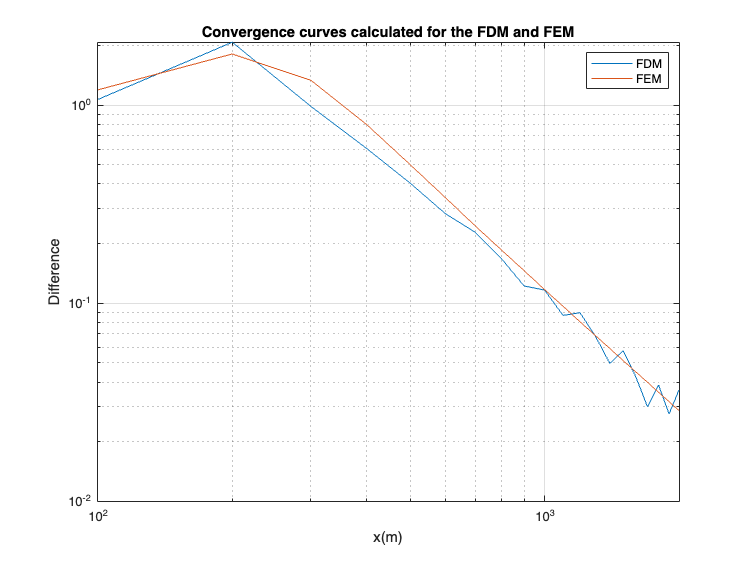

fdm_plot = loglog(x_plot,y_fdm_plot);
grid on;xlabel('x(m)');ylabel('Difference');
hold on
fem_plot = loglog(x_plot,y_fem_plot);

legend([fdm_plot, fem_plot],'FDM','FEM');
hold off
title('Convergence curves calculated for the FDM and FEM')

Comparing convergences curves of FDM and FEM can be stated that bothe of them are approaching to analytical solution, but FEM has better performance.

h=343/freq/8

h = 0.0685

L/h

ans = 1.0074e+03

1. Using the FEM with adequate discretizations, compute the response of the system for frequencies between 1 Hz and the excitation frequency given above, considering two different cases for the properties of medium M2: 															

- The propagation velocity given above; 	

- Only the REAL part of the propagation velocity given above. 												

For each case, present the results graphically: 

- at the interface point between M1 and M2 in terms of the real, imaginary and absolute values of the acoustic pressure for each frequency. 

-  in a colormap plot, for position x frequency, in terms of a sound pressure level with a reference 1 Pa (20*log10(P/1.0)). 

Analyze and comment the results. 

freqs=1:freq;

npts = 600;
n1=floor(npts*L1/L);   n2=ceil(npts*L2/L);
 dx1=L1/n1;      dx2=L2/n2;
x_range1=0:dx1:L1;
x_range2=L1:dx2:L;
x = [x_range1 x_range2];
x(npts+1)=[];
% dx=c1/freq/8;
% n1=dx*L1;   n2=dx*L2;
% npts=n1+n2
% x=0:dx:L;

l_freq = length(freqs);
y_freq_plot = zeros(l_freq,1);
y_freq_r_plot = zeros(l_freq,1);
C=zeros(freq,npts+1);
C_r=zeros(freq,npts+1);
size(C(1,:)), size(C_r(1,:))

ans =      1   601


ans =      1   601


% different discretization for each length
for ii=1:l_freq

%     Calculation numerical and analytical solution 
    P=fem_1D(freqs(ii),c1,c2,L1,L2,n1,n2,rho);
    P_r=fem_1D(freqs(ii),c1,real(c2),L1,L2,n1,n2,rho);

%   the numerical estimation of the pressure (P) at the interface between the two media
    y_freq_plot(ii) = P(n1);
    y_freq_r_plot(ii) = P_r(n1);
    
    C(ii,:)=P;
    C_r(ii,:)=P_r;
%   the error in the numerical estimation of the presssure (P) at the interface between the two media

end

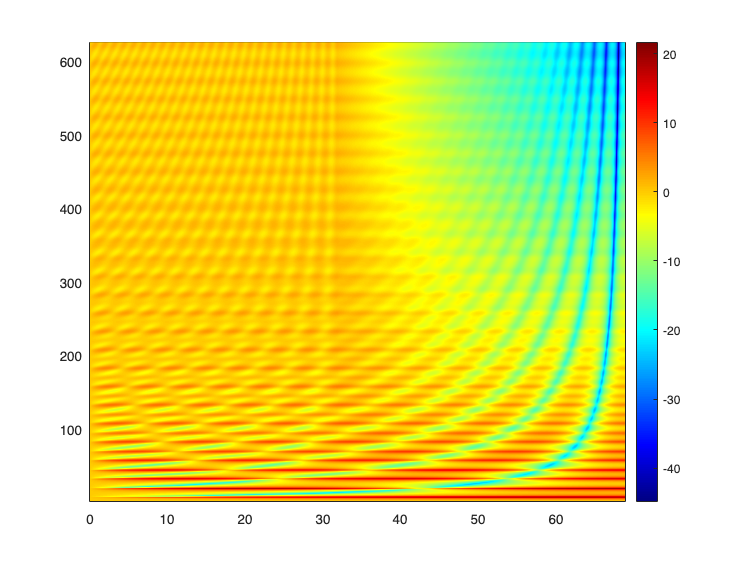

pcolor(x,freqs, 20*log10(abs(C)));
colormap(jet);
colorbar;
shading interp;

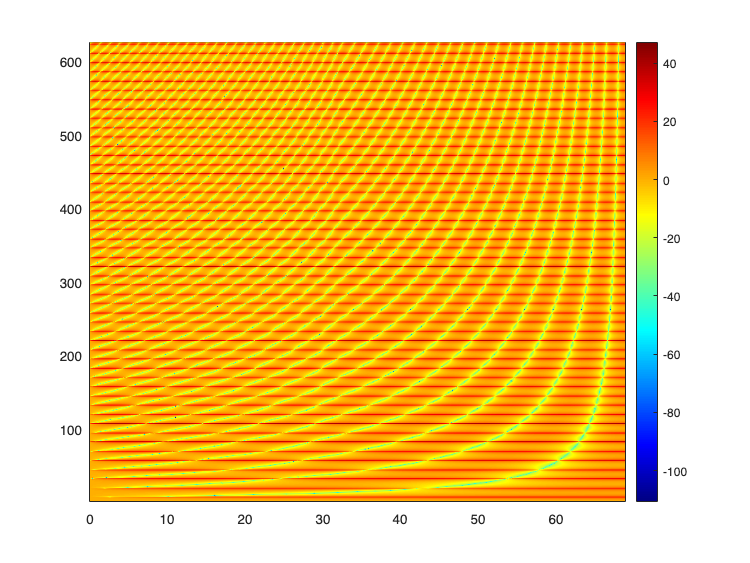

pcolor(x,freqs, 20*log10(abs(C_r)));
colormap(jet);
colorbar;
shading interp;

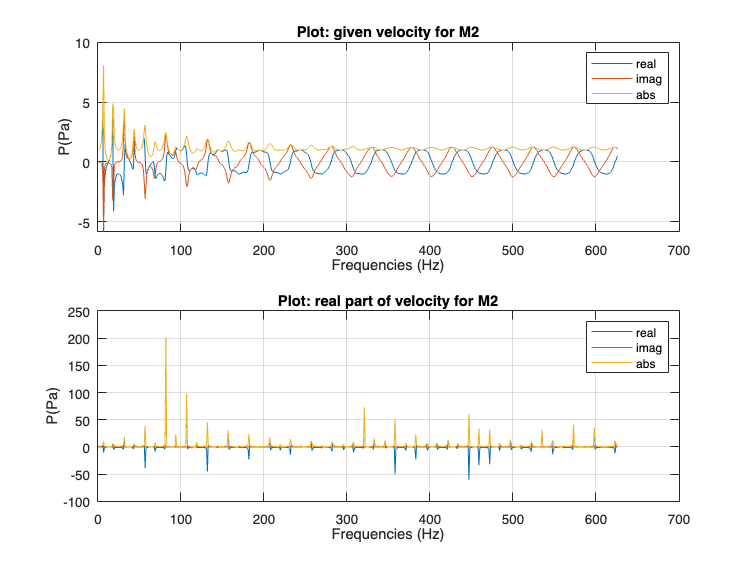

tiledlayout(2,1)

% Top plot
nexttile
p1=plot(freqs,real(y_freq_plot));
grid on;xlabel('Frequencies (Hz)');ylabel('P(Pa)');
hold on
p2=plot(freqs,imag(y_freq_plot));
p3=plot(freqs,abs(y_freq_plot));
hold off
legend([p1,p2,p3],{'real','imag','abs'})

title('Plot: given velocity for M2')

% Bottom plot
nexttile
p21=plot(freqs,real(y_freq_r_plot));
grid on;xlabel('Frequencies (Hz)');ylabel('P(Pa)');
hold on
p22=plot(freqs,imag(y_freq_r_plot));
p23=plot(freqs,abs(y_freq_r_plot));
hold off
legend([p21,p22,p23],{'real','imag','abs'})
title('Plot: real part of velocity for M2')